# Moment of Inertia of a Thin Cylindrical Rod

We will solve for the moment of inertial of a solid, constant density cylindrical rod, where we can assume that the rod's radius ($r$) is much smaller than its length $l$.  As the body is symmetric and uniform, we know that its center of mass is in its geometric center, and we place our body-fixed frame such that $\mathbf{b}_2$ points along the rod (due to symmetry, the placement of $\mathbf{b}_1$ and $\mathbf{b}_2$ is arbitrary.   

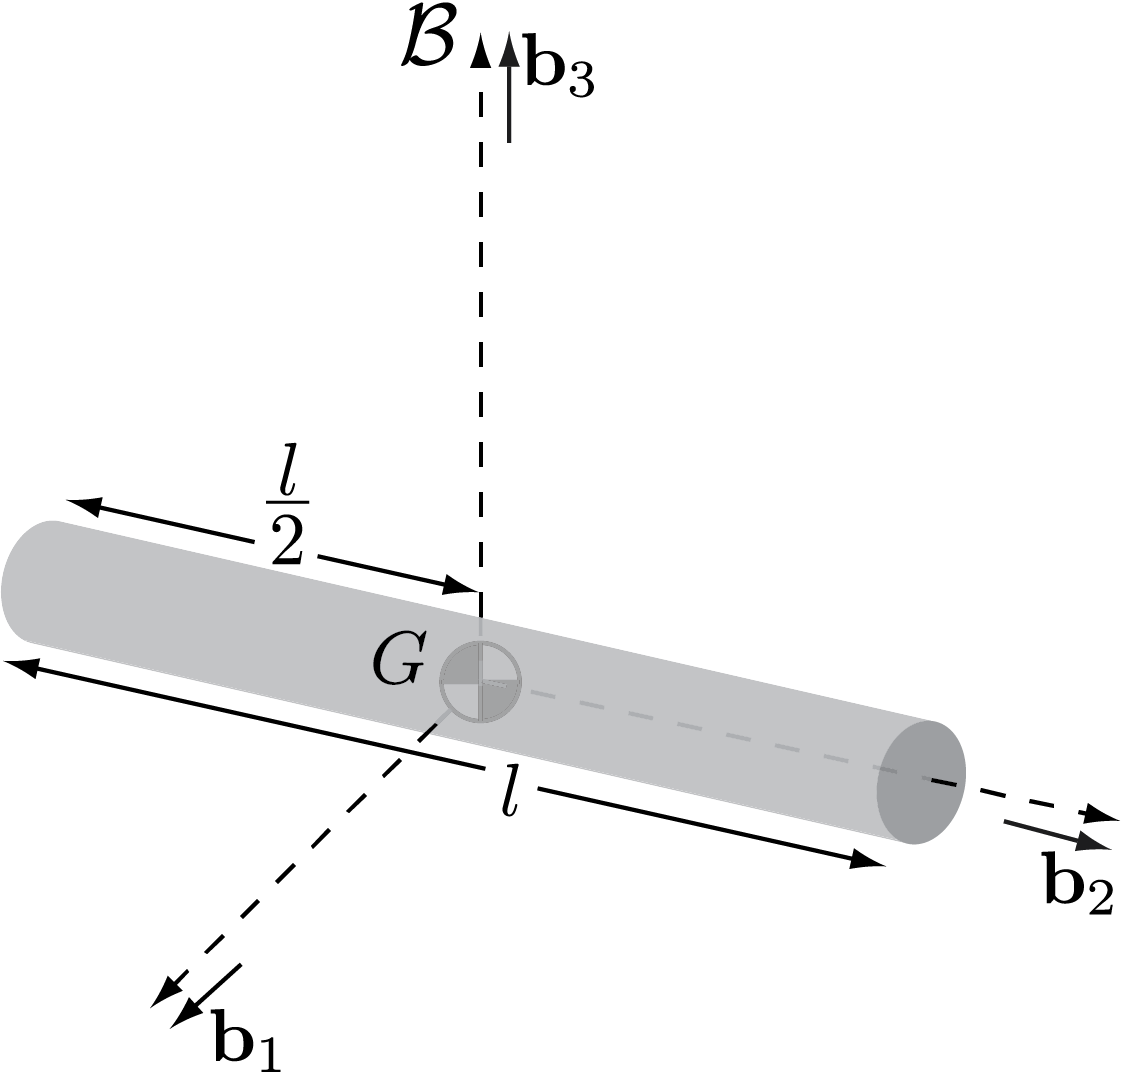

We will defint the position of our differential mass element with respect to the center of mass in cylindrical coordinates, such that $\mathbf r_{\mathrm{d}m/G} = r\cos(\theta)\mathbf b_1 + z \mathbf b_2 +  r\sin(\theta)\mathbf{b}_3$

syms r theta m h l 'positive'
syms z 'real'

r_dmG = [r*cos(theta);z;r*sin(theta)] %position of dm wrt G in B frame components

$$r\_dmG = \left(\begin{array}{c} r\,\cos\left(\theta \right)\\ z\\ r\,\sin\left(\theta \right) \end{array}\right)$$

The integrand of the moment of inertia tensor is given by $\mathbf r_{\mathrm{d}{m}/O} \cdot \mathbf r_{\mathrm{d}{m}/O}  \mathbb{U} - \mathbf r_{\mathrm{d}{m}/O} \otimes \mathbf r_{\mathrm{d}{m}/O}$. In component form and linear algebraic operations, this is:

integrand = dot(r_dmG,r_dmG)*eye(3) - r_dmG*transpose(r_dmG)

$$integrand = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2}+z^{2} & -r\,z\,\cos\left(\theta \right) & \sigma_{1}\\ -r\,z\,\cos\left(\theta \right) & \sigma_{3}+\sigma_{2} & -r\,z\,\sin\left(\theta \right)\\ \sigma_{1} & -r\,z\,\sin\left(\theta \right) & \sigma_{3}+z^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-r^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\\ \sigma_{2}=r^{2}\,{\sin\left(\theta \right)}^{2}\\ \sigma_{3}=r^{2}\,{\cos\left(\theta \right)}^{2} \end{array}$$

Remember our assumption that $r \ll l$.  This means that we can neglect any terms that are of order $r^2$.  We can do this before or after evaluating the integral, but as it will cause some of the componetns of the matrix to go to zero, it is easiest to do so before integrating:

integrand = subs(integrand, r^2, 0)

$$integrand = \left(\begin{array}{ccc} z^{2} & -r\,z\,\cos\left(\theta \right) & 0\\ -r\,z\,\cos\left(\theta \right) & 0 & -r\,z\,\sin\left(\theta \right)\\ 0 & -r\,z\,\sin\left(\theta \right) & z^{2} \end{array}\right)$$

The limits of integration are that $r$ varies from 0 to $r$, $\theta$ varies from 0 to $2\pi$, and $z$ varies from $-\frac{l}{2}$ to $\frac{l}{2}$.  Remember also that the differential volume element for cylindrical coordinates is given by $\mathrm{d}V = r \mathrm{d}r \mathrm{d}\theta \mathrm{d}z$.

tmp = int(int(int(integrand*r,r, [0,r]), theta, [0, 2*pi]), z, [-l/2,l/2])

$$tmp = \left(\begin{array}{ccc} \frac{\pi \,l^{3}\,r^{2}}{12} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & \frac{\pi \,l^{3}\,r^{2}}{12} \end{array}\right)$$

Finally, the moment of inertia matrix is equal to this integral scaled by the density, which is given by the cylinder's mass $m$ divided by its volume $\pi r^2 l$:

I_G = m/(pi*r^2*l)*tmp

$$I\_G = \left(\begin{array}{ccc} \frac{l^{2}\,m}{12} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & \frac{l^{2}\,m}{12} \end{array}\right)$$

Now let's consider rotation of the rod about one of its end-points.  We will apply the parallel axis theorem $[\mathbb I_Q]_\mathcal B = [\mathbb I_G]_\mathcal B + m_G \left(\|\mathbf r_{Q/G}\|^2  I_{3 \times 3} - [\mathbf r_{Q/G}]_\mathcal B [\mathbf r_{Q/G}]_\mathcal B^T \right)$.  In this case (with $Q$ representing the end-point of the rod), $\mathbf{r}_{Q/G} = \frac{l}{2}\mathbf{b}_2$

r_QG = [0;l/2;0] %position of Q wrt G in B frame components

$$r\_QG = \left(\begin{array}{c} 0\\ \frac{l}{2}\\ 0 \end{array}\right)$$

I_Q = I_G + m*(dot(r_QG,r_QG)*eye(3) - r_QG*r_QG.')

$$I\_Q = \left(\begin{array}{ccc} \frac{l^{2}\,m}{3} & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & \frac{l^{2}\,m}{3} \end{array}\right)$$